# MAS416 - Tutorial 7

## Problem 3a) Position error

clc; clear all; close all;

rho = 850; % kg/m^3
beta = 900*10^6; % N/m^2
Cd = 0.55;
Ad0 = 2/10^6; % m^2
Admax = 15/10^6; % m^2
Admin = 0; % m^2
d = 63/10^3; % m
A = pi/4 * d^2; % m^2
m = 3200; % kg
g = 9.81; % m/s^2

V2min = 2000/10^6; % m^3
y = 0; % m
yDot = 0; % m/s

p1 = 150*10^5; % Pa
p2 = (m*g)/A; % p = F/A, Pa
p3 = 0; % Pa

t = 0; % s
dt = 10^-6; % s
idx = 1; % Counter
simTime = 8; % s

yref = 20/10^3; % m

Kp = 0.0001;
tau_i = 1.3;
y_err = 0;
yDot_err_int = 0;

while(t <= simTime)
    % Calculations

    Ad = -Kp * y_err - Kp/tau_i * yDot_err_int;
    % Saturate Ad
    if(Ad >= Admax)
        Ad = Admax;
    elseif(Ad <= Admin)
        Ad = Admin;
    end
    
    % Position error
    y_err = yref - y;

    % Flow calculation
    Q1 = Cd*Ad0*sign((p1-p2)) * sqrt(2/rho * abs(p1-p2));
    Q2 = Cd*Ad *sign((p2-p3)) * sqrt(2/rho * abs(p2-p3));

    % Variable volume of cylinder
    V2 = V2min + y*A;

    % F = ma --> a = F/m --> yDotDot = F/m
    % p = F/A --> F1 = p*A
    % F2 = m*g
    % F_sum = F1-F2
    yDotDot = (p2*A-m*g)/m;
    % p1 and p3 are constant, but p2 is changing, therefore we need to
    % integrate it
    p2Dot = beta/V2 * (Q1-Q2-yDot*A);
    % Negative sign on -yDot*A since positive y is upwards and therefore
    % the oil is flowing into the cylinder, thus negative flow.

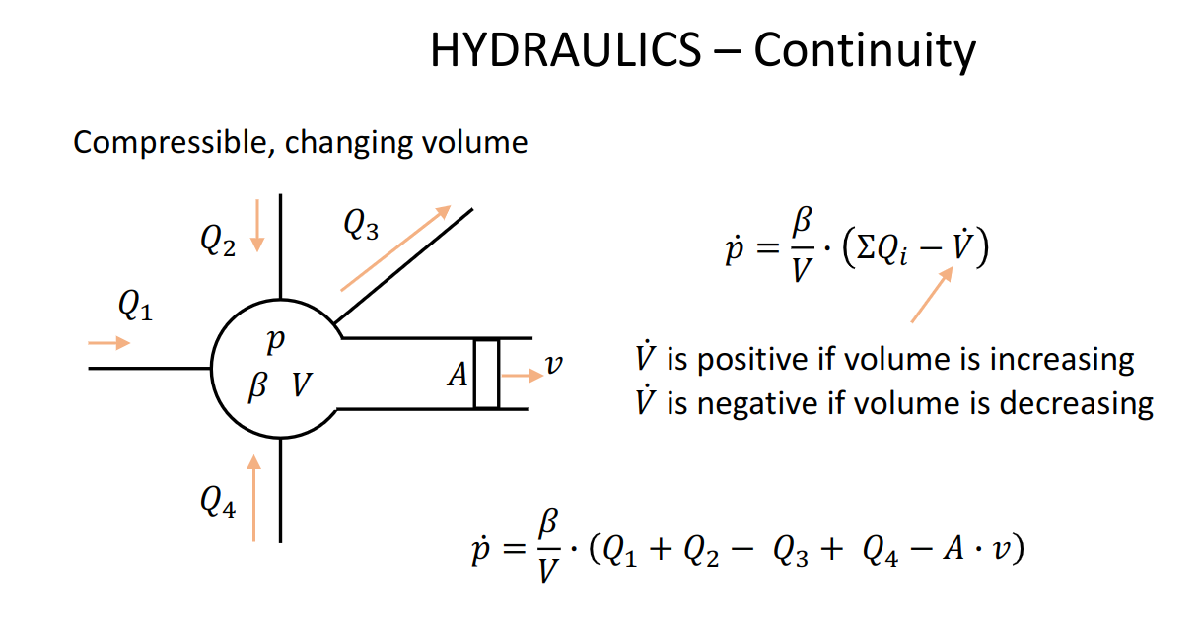

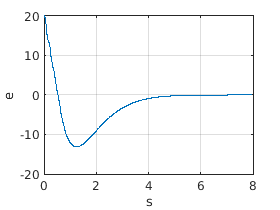

    % Logging
    t_plt(idx) = t;
    yDot_err_plt(idx) = y_err*1000; % mm
    % Time integration
    p2 = p2 + p2Dot * dt;
    yDot = yDot + yDotDot * dt;
    y = y + yDot * dt;

    yDot_err_int = yDot_err_int + y_err * dt;

    % Updating variables
    t = t + dt;
    idx = idx + 1;
end

plot(t_plt, yDot_err_plt)
grid
xlabel("s")
ylabel("e")

## Problem 3b) Velocity error

clc; clear all;

rho = 850; % kg/m^3
beta = 900*10^6; % N/m^2
Cd = 0.55;
Ad0 = 2/10^6; % m^2
Admax = 15/10^6; % m^2
Admin = 0; % m^2
d = 63/10^3; % m
A = pi/4 * d^2; % m^2
m = 3200; % kg
g = 9.81; % m/s^2

V2min = 2000/10^6; % m^3
y = 0; % m
yDot = 0; % m/s

p1 = 150*10^5; % Pa
p2 = (m*g)/A; % p = F/A, Pa
p3 = 0; % Pa

t = 0; % s
dt = 10^-6; % s
idx = 1; % Counter
simTime = 8; % s

yDotref = 10/10^3; % m/s

Kp = 0.0001;
tau_i = 1.3;
yDot_err = 0;
yDot_err_int = 0;

while(t <= simTime)
    % Calculations

    Ad = -Kp * yDot_err - Kp/tau_i * yDot_err_int;
    % Saturate Ad
    if(Ad >= Admax)
        Ad = Admax;
    elseif(Ad <= Admin)
        Ad = Admin;
    end
    
    % Position error
    yDot_err = yDotref - yDot;

    % Flow calculation
    Q1 = Cd*Ad0*sign((p1-p2)) * sqrt(2/rho * abs(p1-p2));
    Q2 = Cd*Ad *sign((p2-p3)) * sqrt(2/rho * abs(p2-p3));

    % Variable volume of cylinder
    V2 = V2min + y*A;

    % F = ma --> a = F/m --> yDotDot = F/m
    % p = F/A --> F1 = p*A
    % F2 = m*g
    % F_sum = F1-F2
    yDotDot = (p2*A-m*g)/m;
    % p1 and p3 are constant, but p2 is changing, therefore we need to
    % integrate it
    p2Dot = beta/V2 * (Q1-Q2-yDot*A);
    % Negative sign on -yDot*A since positive y is upwards and therefore
    % the oil is flowing into the cylinder, thus negative flow.

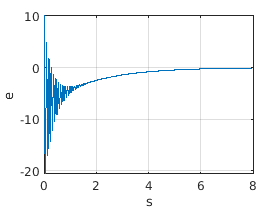

    % Logging
    t_plt(idx) = t;
    yDot_err_plt(idx) = yDot_err*1000; % mm/s
    % Time integration
    p2 = p2 + p2Dot * dt;
    yDot = yDot + yDotDot * dt;
    y = y + yDot * dt;

    yDot_err_int = yDot_err_int + yDot_err * dt;

    % Updating variables
    t = t + dt;
    idx = idx + 1;
end

plot(t_plt, yDot_err_plt)
grid
xlabel("s")
ylabel("e")